# **Welcome to the Cartoon Filter!**

This time we're going to create a filter to give a cartoonish effect to any image we want, and how? With some basic Image Processing :D

The general process can be summarized into the following steps:

- **Loading** the image

- Defining and a applying an **Anisotropic Diffusion filter**

- Mean Shift **Clustering** of the colors in the filtered image

- **Replacing the colors** in the filtered image with the new color mapping from the clusters

- **Recovering borders** and adding them do the filtered image

- Profit

First of all, our always appreciated clearing of variables and loading the image

clear variables; clc; close all;
file = uigetimagefile;
im = imread(file);

Now we resize for simplicity and faster execution times ***(to be removed in final version)***

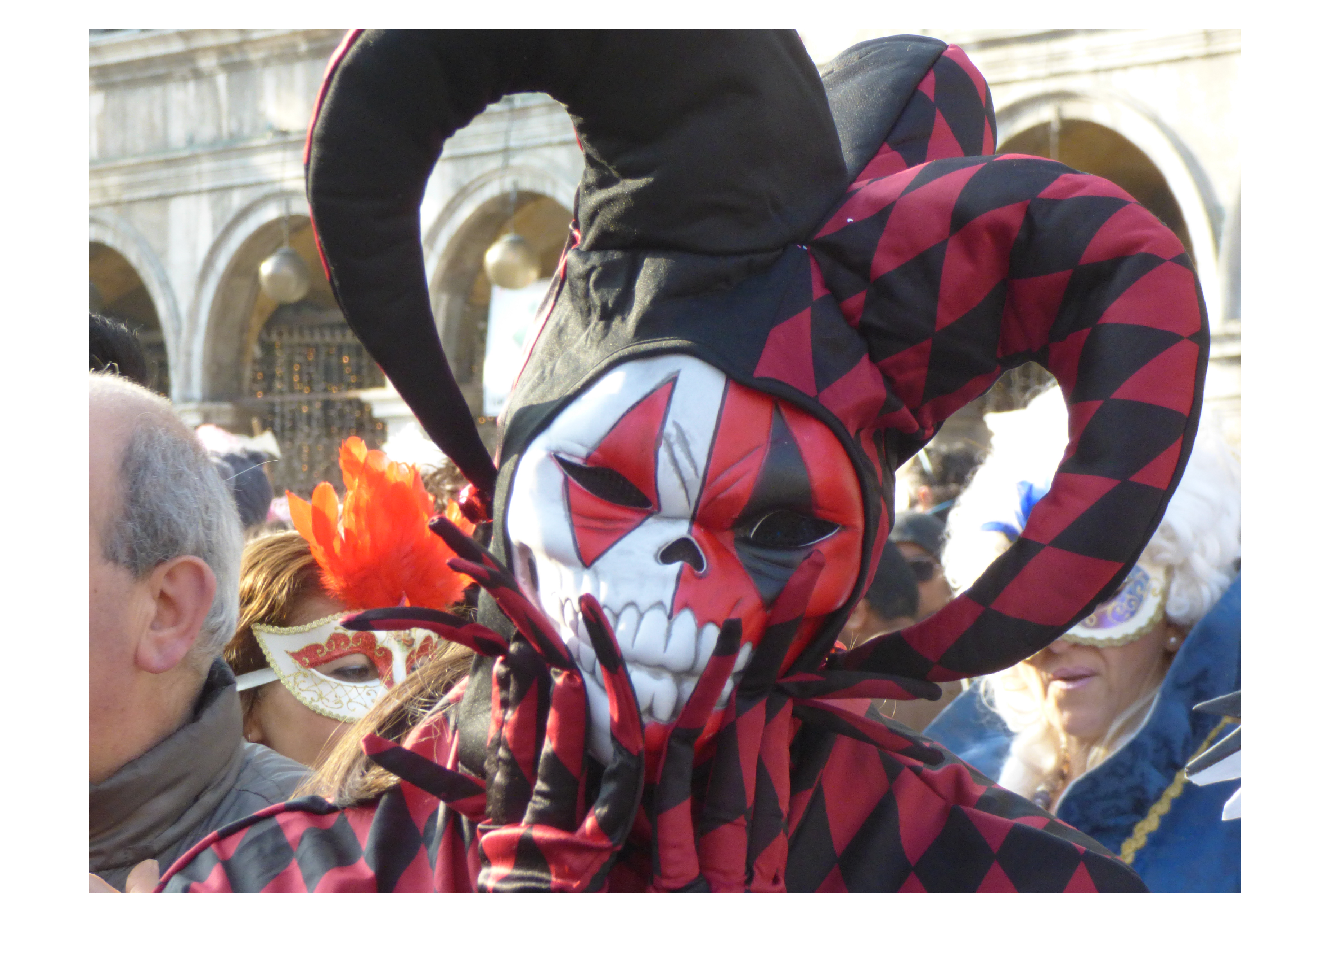

imshow(im);

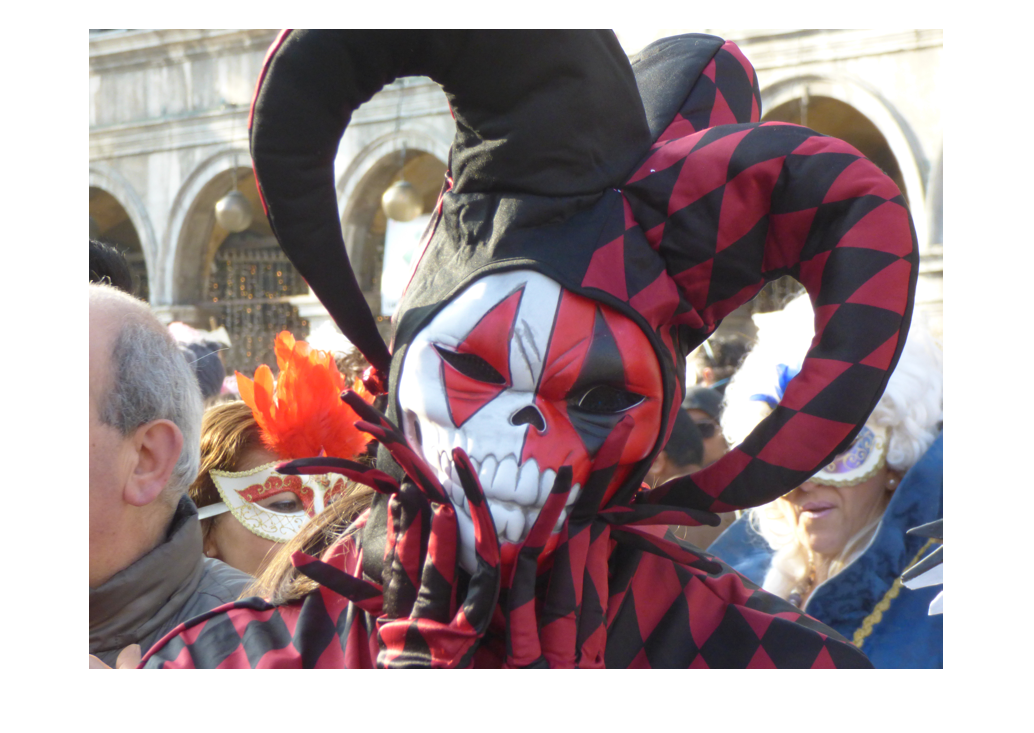

A = imresize(im,[640 NaN],"AntiAliasing",1);
imshow(A);